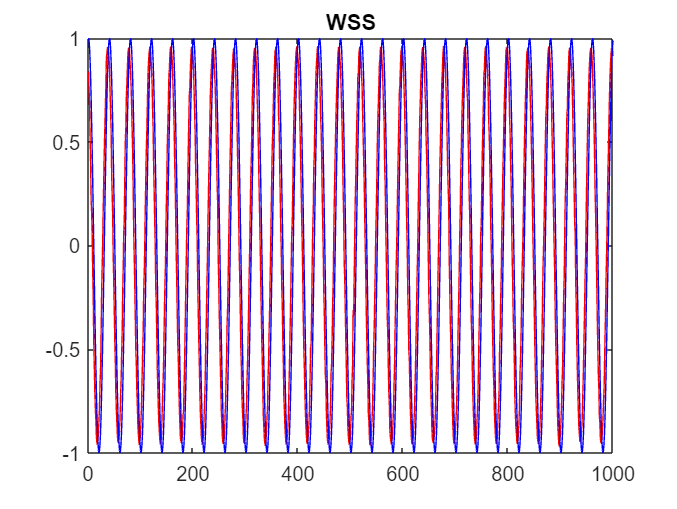

N = 1000;
R = 100;
k = (0:1:N-1)';
fn = 0.025;

for i = 1:R
    phi(:,i) = rand(N,1);
    X = cos(2*pi*fn*k); % True Mean
    X_rn(:,i) = cos((2*pi*fn*k) + phi(:,i)); % randomness due to the phase
end    

mu = mean(X_rn,2); %Ensemble Average
% Ensemble average coincides with Theoretical Mean
plot(mu, 'r')
hold on;
plot(X, 'b')
title('WSS')
hold off;

cov_lag1 = cov(X_rn(:,1),X_rn(:,2))

cov_lag1 =     0.5052    0.4633
    0.4633    0.5012


cov_lag_1 = cov(X_rn(:,49),X_rn(:,50))

cov_lag_1 =     0.5039    0.4598
    0.4598    0.4968



cov_lag9 = cov(X_rn(:,1),X_rn(:,10))

cov_lag9 =     0.5052    0.4582
    0.4582    0.4905


cov_lag_9 = cov(X_rn(:,81),X_rn(:,90))

cov_lag_9 =     0.5039    0.4603
    0.4603    0.4962



if (round((cov_lag1(1,2) - cov_lag_1(1,2))) == 0)
    fprintf('Covarience only depends on lag')
else 
    fprintf('Covarience only depends on both lag and time')
end    

Covarience only depends on lag